# Solving Nonlinear Equations

We wish to find the intersection between the two curves


$$P\left(q\right)=P_0 -a_P \;q^2$$



$$N\left(q\right)=a_N \;q^2$$


P0 = 120;
aP = 3e-4;
aN = 7e-4;

P = @(q) P0-aP*q.^2;
N = @(q) aN*q.^2;

q = linspace(0,500);

plot(q,P(q),q,N(q))
hold on


To do so, we try to find where $P\left(q\right)-N\left(q\right)=0$ using a nonlinear solver, to which we give the initial guess $q_0 =300$

q_eq = fsolve(@(q) P(q)-N(q),300);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


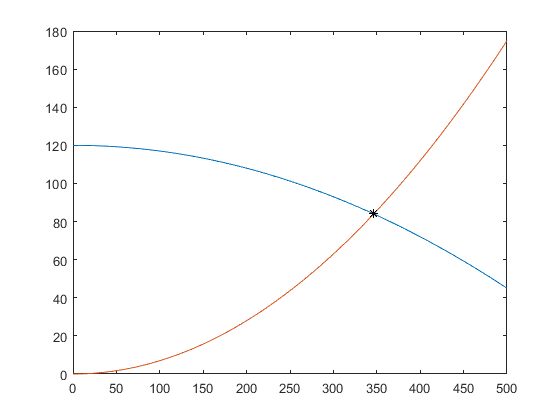

plot(q_eq,N(q_eq),'*k')

Unfortunately, the solution found will depend on the initial guess. Any positive $q_0$ will result in the desired point, but any negative $q_0$ will instead identify the other point in which the two curves meet 

figure
plot(q,P(q),q,N(q),q_eq,N(q_eq),'*k')
hold on

q_eq2 = fsolve(@(q) P(q)-N(q),-1);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


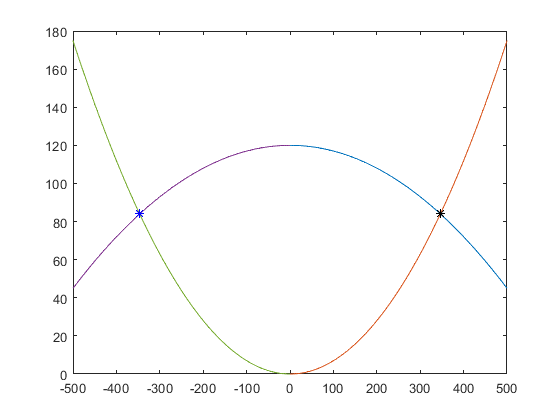

q = linspace(-500,0);
plot(q,P(q),q,N(q),q_eq2,N(q_eq2),'*b')

Even worse, if we give the initial guess $q_0 =0$, the solver won't even converge.

figure
q = linspace(0,500);
plot(q,P(q),q,N(q),q_eq,N(q_eq),'*k')
hold on

q = linspace(-500,0);
plot(q,P(q),q,N(q),q_eq2,N(q_eq2),'*b')

q_nc = fsolve(@(q) P(q)-N(q),0);


No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the function tolerance.

<stopping criteria details>


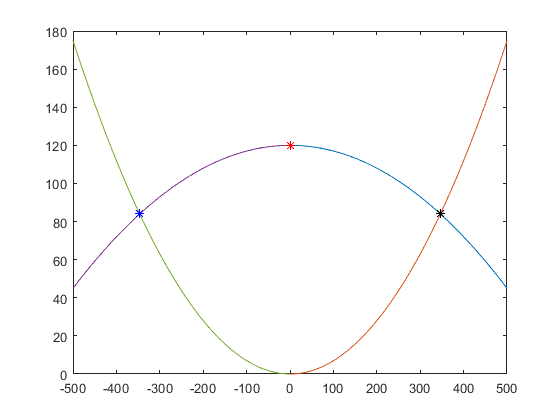

plot(q_nc,P(q_nc),'*r')

# Minimizing a Function

We wish to find the minimum of the function


$$f\left(x\right)={\mathrm{ax}}^2 +\mathrm{bx}+c$$


a = 3;
b = 40;
c = 100;

f = @(x) a*x.^2+b*x+c;

figure
x = linspace(-40,40);
plot(x,f(x))
hold on

To do so, we use `fminsearch` with the initial guess $x_0 =0$

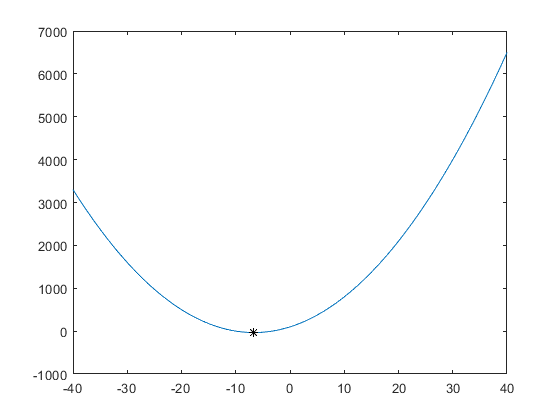

x1 = fminsearch(f,0);

plot(x1,f(x1),'*k')

In this case, e find the minimum regardless of the initial guess. However, the same is not true for all functions.

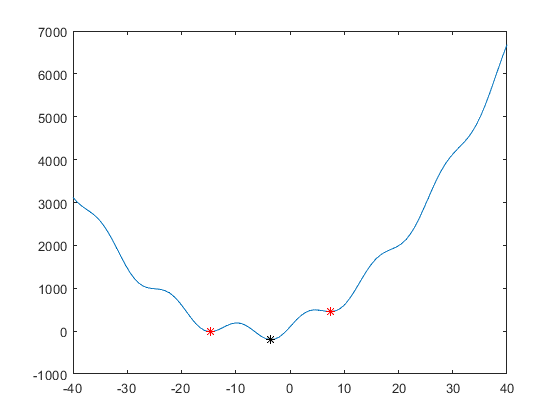

c = 200;

g = @(x) f(x)+c*sin(x/2);

figure
plot(x,g(x))

hold on
x1 = fminsearch(g,-15);
plot(x1,g(x1),'*r')
x2 = fminsearch(g,0);
plot(x2,g(x2),'*k')
x3 = fminsearch(g,15);
plot(x3,g(x3),'*r')

This is because numerical solvers are able to find **local minima**, but provide no guarantee that they will find the **global minimum**.